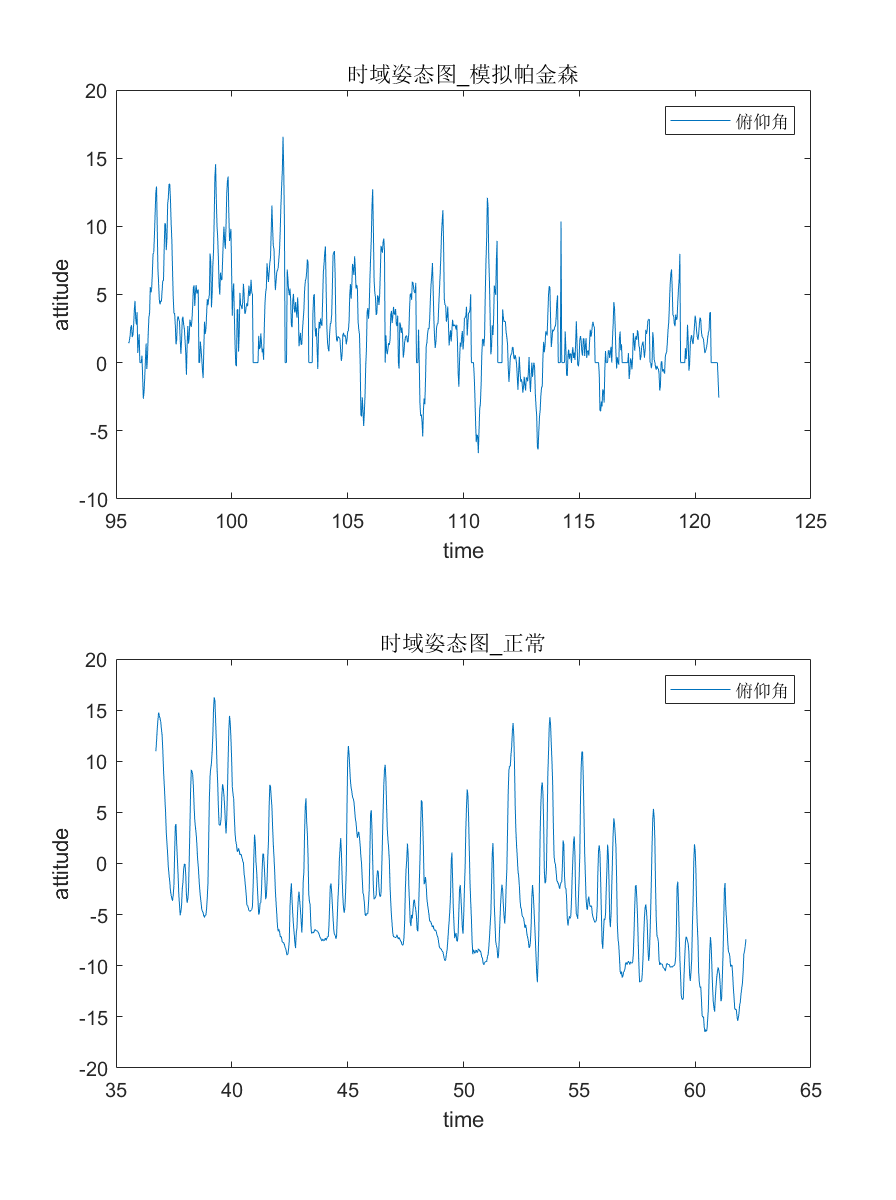

load("dataset_pd.mat");
load("dataset_upd.mat");

figure('units','normalized','position',[0.1,0.1,0.7,1.5]);
subplot(2,1,1);
%导入模拟帕金森写字的数据
plot(dataset_pd{:, "time"}, dataset_pd{:, "pitch"});
xlabel("time");
ylabel("attitude");
title('时域姿态图\_模拟帕金森');
legend('俯仰角');
subplot(2,1,2);
%导入正常写字的数据
plot(dataset_upd{:, "time"}, dataset_upd{:, "pitch"});
xlabel("time");
ylabel("attitude");
title('时域姿态图\_正常');
legend('俯仰角');

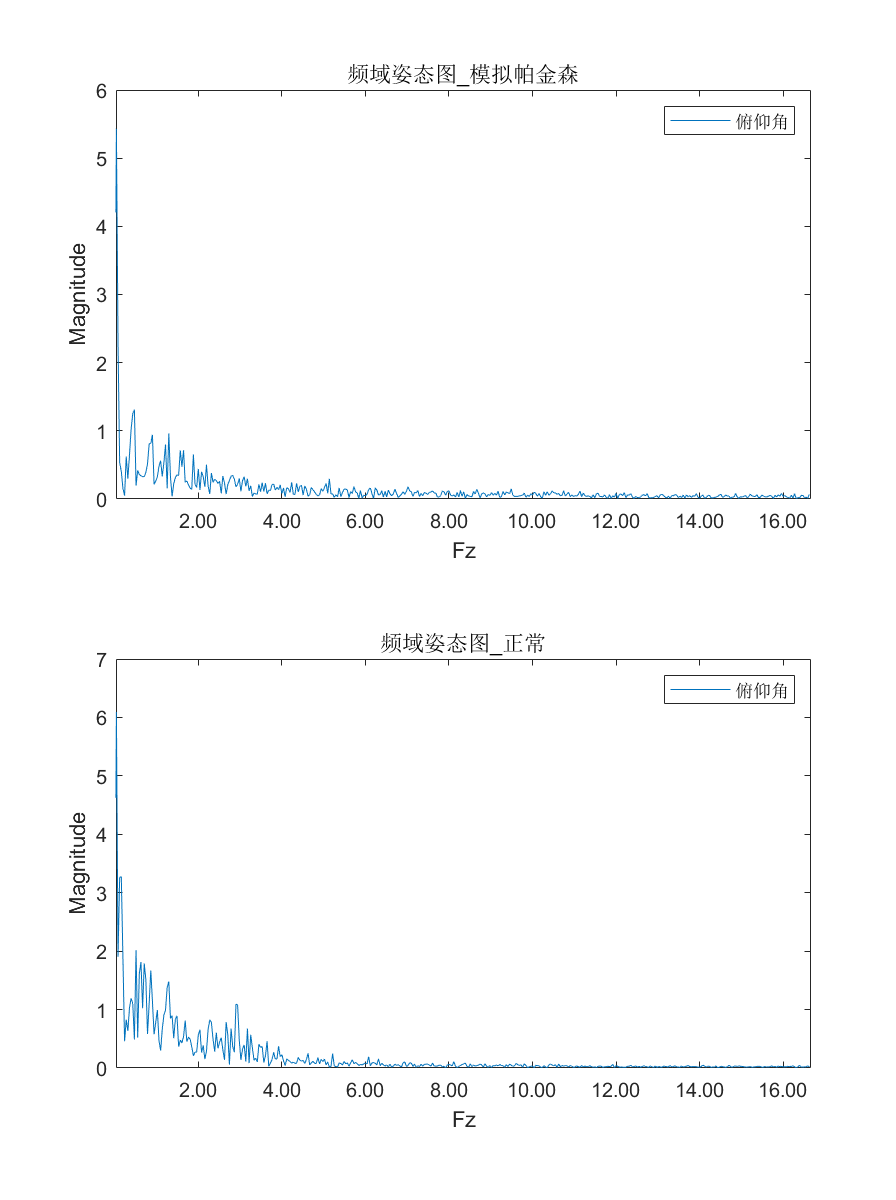


figure('units','normalized','position',[0.1,0.1,0.7,1.5]);
%序列长度
N1 = length(dataset_pd{:, "pitch"});
%采样频率
Fs = 1 / 0.03;
%快速傅里叶变换
dataset_pitch_f = abs(fftshift(fft(dataset_pd{:, "pitch"})));
%仅取0~Fs并进行幅值修正
pitch_fft = 2 * dataset_pitch_f(N1 / 2 : N1 - 1) / N1;%修正交流
pitch_fft(1) = pitch_fft(1) / 2;%修正直流

%快速傅里叶变换
dataset_roll_f = abs(fftshift(fft(dataset_pd{:, "roll"})));
%仅取0~Fs并进行幅值修正
roll_fft = 2 * dataset_roll_f(N1 / 2 : N1 - 1) / N1;%修正交流
roll_fft(1) = roll_fft(1) / 2;%修正直流

%快速傅里叶变换
dataset_yaw_f = abs(fftshift(fft(dataset_pd{:, "yaw"})));
%仅取0~Fs并进行幅值修正
yaw_fft = 2 * dataset_yaw_f(N1 / 2 : N1 - 1) / N1;%修正交流
yaw_fft(1) = yaw_fft(1) / 2;%修正直流

%x轴
f1 = (N1 / 2 : N1 - 1) * Fs / N1 - Fs / 2;

subplot(2,1,1);
plot(f1, pitch_fft);
xlabel("Fz");
xlim([1/Fs Fs/2]);
xtickformat('%.2f');
ylabel("Magnitude");
title('频域姿态图\_模拟帕金森');
legend('俯仰角');

%序列长度
N2 = length(dataset_upd{:, "pitch"});
%快速傅里叶变换
dataset_pitch_uf = abs(fftshift(fft(dataset_upd{:, "pitch"})));
%仅取0~Fs并进行幅值修正
pitch_fft_u = 2 * dataset_pitch_uf(N2 / 2 : N2 - 1) / N2;%修正交流
pitch_fft_u(1) = pitch_fft_u(1) / 2;%修正直流

%快速傅里叶变换
dataset_roll_uf = abs(fftshift(fft(dataset_upd{:, "roll"})));
%仅取0~Fs并进行幅值修正
roll_fft_u = 2 * dataset_roll_uf(N2 / 2 : N2 - 1) / N2;%修正交流
roll_fft_u(1) = roll_fft_u(1) / 2;%修正直流

%快速傅里叶变换
dataset_yaw_uf = abs(fftshift(fft(dataset_upd{:, "yaw"})));
%仅取0~Fs并进行幅值修正
yaw_fft_u = 2 * dataset_yaw_uf(N2 / 2 : N2 - 1) / N2;%修正交流
yaw_fft_u(1) = yaw_fft_u(1) / 2;%修正直流

%x轴
f2 = (N2 / 2 : N2 - 1) * Fs / N2 - Fs / 2;

subplot(2,1,2);
plot(f2, pitch_fft_u);
xlabel("Fz");
xlim([1/Fs Fs/2]);
xtickformat('%.2f');
ylabel("Magnitude");
title('频域姿态图\_正常');
legend('俯仰角', 'roll', 'yaw');

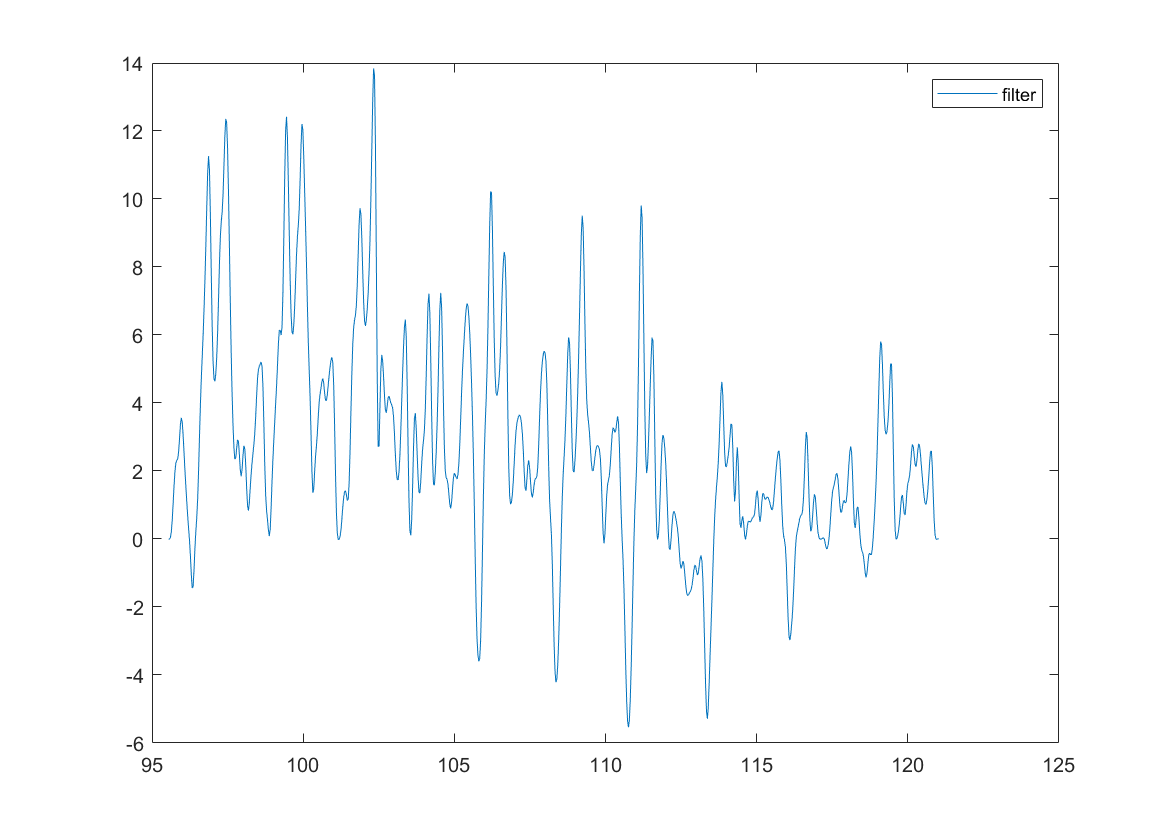

%将模拟帕金森与正常的频域做差
% pitch_fft_sub = pitch_fft - pitch_fft_u;
% roll_fft_sub = roll_fft - roll_fft_u;
% yaw_fft_sub = yaw_fft - yaw_fft_u;
% 
% plot(f2, pitch_fft_sub, f2, roll_fft_sub, f2, yaw_fft_sub);
% xlabel("Fz");
% xlim([1/Fs Fs/2]);
% xtickformat('%.2f');
% ylabel("Magnitude");
% title('频域姿态图-做差');
% legend('pitch', 'roll', 'yaw');
%对模拟帕金森信号进行滤波，采用有限脉冲响应滤波器FIR，通过对频域加窗滤除帕金森震颤带来的影响，还原出没有震颤的数据。
%这里假设模拟和正常除了震颤其他因素都一样，即上述做差得到的非零值都是应该滤除的
%窗函数
% h = (1 : N1);
% tao = (N1 - 1) / 2;
% for i = 1 : N1
%     if i == tao
%         h(i) = 1 - 2 / pi + 1 / pi;
%     else
%         h(i) = (1 / (pi * (i - tao))) * (sin(pi * (i -tao)) - sin(2 * (i - tao) + sin(1 * (i - tao))));
%     end
% end
% 
% h_fft = abs(fftshift(fft(h)));
% h__fft = 2 * h_fft(N2 / 2 : N2 - 1) / N2;%修正交流
% h__fft(1) = h__fft(1) / 2;%修正直流
% plot(f1, h__fft);
% 设计1.5 Hz的低通FIR滤波器
cutoffFreq = 4; % 截止频率为4Hz
filterOrder = 10;
% 使用窗口方法设计FIR滤波器
window = hamming(filterOrder + 1); % 使用汉明窗口
b = fir1(filterOrder, cutoffFreq / (Fs / 2), 'low', window);

% 应用滤波器来滤除1 Hz到2 Hz之间的信号成分
pitch_filter = filter(b, 1, dataset_pd{:, "pitch"});
roll_filter = filter(b, 1, dataset_pd{:, "roll"});
yaw_filter = filter(b, 1, dataset_pd{:, "yaw"});

figure('units','normalized','position',[0.1,0.1,0.7,0.8]);
plot(dataset_pd{:, "time"}, pitch_filter)
legend("filter")

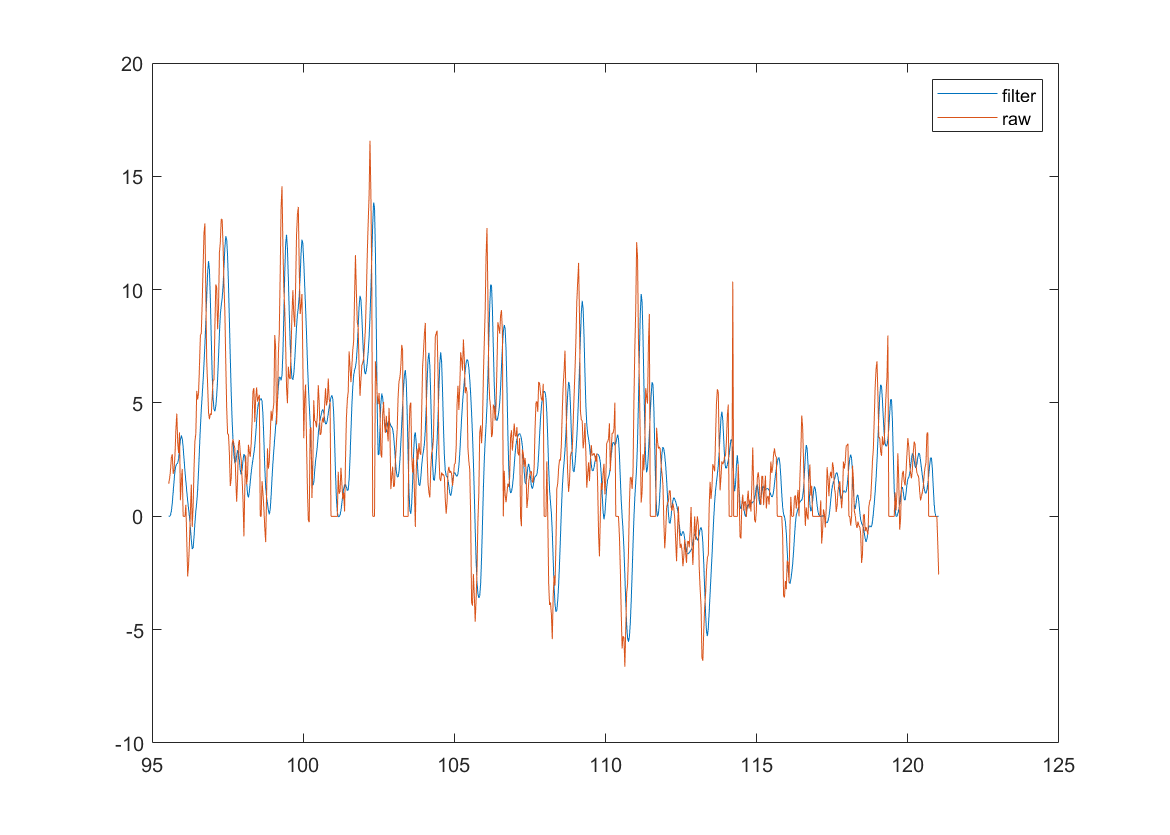

plot(dataset_pd{:, "time"}, pitch_filter, dataset_pd{:, "time"}, dataset_pd{:, "pitch"})
legend("filter", "raw")

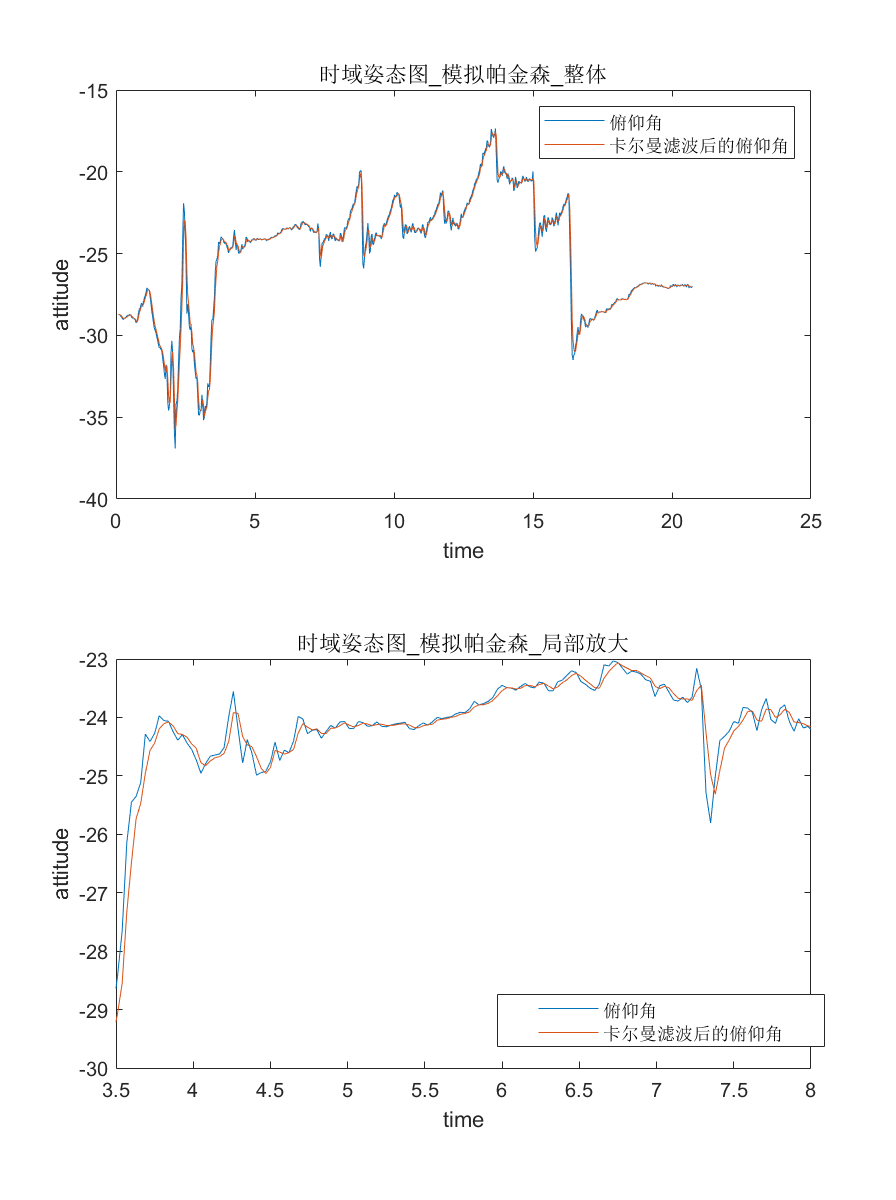

% plot(dataset_pd{:, "time"}, roll_filter, dataset_pd{:, "time"}, dataset_pd{:, "roll"})
% legend("filter", "raw")
% plot(dataset_pd{:, "time"}, yaw_filter, dataset_pd{:, "time"}, dataset_pd{:, "yaw"})
% legend("filter", "raw")
% % 初始化卡尔曼滤波器参数
% initial_state_estimate = 0; % 初始状态估计
% initial_estimate_error = 0.02; % 初始状态估计的误差方差
% process_noise_stddev = 0.02; % 状态转移噪声的标准差
% measurement_noise_stddev = 0.09;
% 
% % 初始化滤波器状态和误差方差
% state_estimate = initial_state_estimate;
% estimate_error = initial_estimate_error;
% 
% % 存储估计的状态
% filtered_state_estimates = zeros(1, N1);
% 
% % 卡尔曼滤波
% for t = 1:N1
%     % 预测步骤（状态估计的预测）
%     predicted_state_estimate = state_estimate;
%     predicted_estimate_error = estimate_error + process_noise_stddev^2;
%     
%     % 更新步骤（根据观测值来更新状态估计）
%     kalman_gain = predicted_estimate_error / (predicted_estimate_error + measurement_noise_stddev^2);
%     state_estimate = predicted_state_estimate + kalman_gain * (dataset_pd{:, 'pitch'}(t) - predicted_state_estimate);
%     estimate_error = (1 - kalman_gain) * predicted_estimate_error;
%     
%     % 存储估计的状态
%     filtered_state_estimates(t) = state_estimate;
% end
% 
% plot(dataset_pd{:, 'time'}, filtered_state_estimates, dataset_pd{:, 'time'}, dataset_pd{:, 'pitch'})
% legend('filter', 'raw')
% %快速傅里叶变换
% filtered_state_estimates_fft = abs(fftshift(fft(filtered_state_estimates)));
% %仅取0~Fs并进行幅值修正
% filtered_state_estimates_fft1 = 2 * filtered_state_estimates_fft(N1 / 2 : N1 - 1) / N1;%修正交流
% filtered_state_estimates_fft1(1) = filtered_state_estimates_fft1(1) / 2;%修正直流
% 
% plot(f1, filtered_state_estimates_fft1, f1, pitch_fft);
% legend('pitch_filter', 'pitch')
load("wo_pd.mat")
figure('units','normalized','position',[0.1,0.1,0.7,1.5])
subplot(2,1,1)
plot(wo_pd.time, wo_pd.pitch, wo_pd.time, wo_pd.filter_pitch);
xlabel("time")
ylabel("attitude")
title('时域姿态图\_模拟帕金森\_整体')
legend('俯仰角', '卡尔曼滤波后的俯仰角');

subplot(2,1,2)
plot(wo_pd.time, wo_pd.pitch, wo_pd.time, wo_pd.filter_pitch);
xlabel("time")
ylabel("attitude")
xlim([3.5 8])
title('时域姿态图\_模拟帕金森\_局部放大')
legend('俯仰角', '卡尔曼滤波后的俯仰角');

subplot(2,1,2)
legend('Position',[0.5943,0.12771,0.28627,0.043125])